CS 567 (HW2)

Sparsh Agarwal

9075905142

Q1.

red = [1 0; 0 0]

red =      1     0
     0     0


green = [ 0 1; 0 0]

green =      0     1
     0     0


blue = [0 0; 1 1]

blue =      0     0
     1     1


% test_image = cat(3, red, green, blue);
% image(test_image)

Q2.

img_snr = zeros(8,1);
img_cnr = zeros(8,1);   
for i=1:8
    sfa = bucky_images(300:350,1:100,i);
    img_snr(i)=mean(mean(bucky_images(:,:,i)))/std(sfa(:));
    img_cnr(i)=mean(max(bucky_images(:,:,i))-min(bucky_images(:,:,i)))/std(sfa(:));
end

a.

img_snr

img_snr =     4.1879
    4.3249
    4.3532
    5.8625
    4.3361
    4.2136
    4.3574
    7.3955


b.

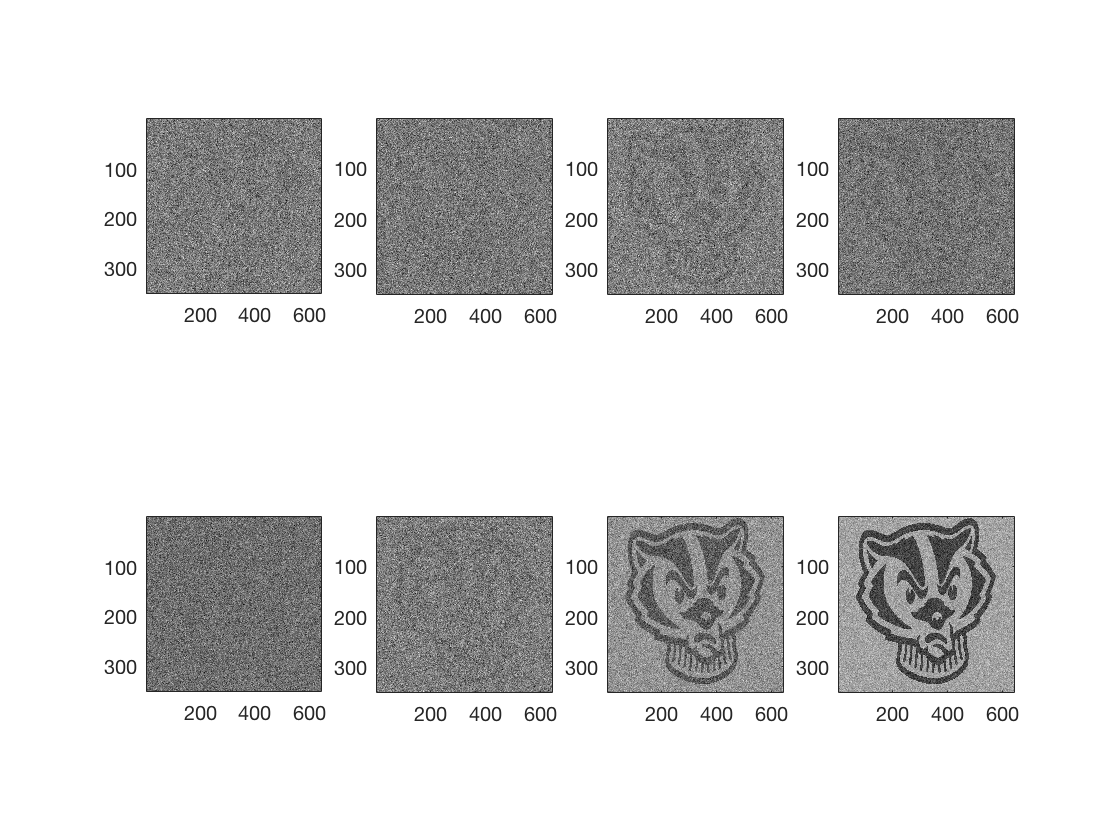

[snr,idx] = sort(img_snr);

figure
colormap('gray')
for i=1:2
    for j=1:4
        subplot(2,4,(4*(i-1))+j)
        test_img = bucky_images(:,:,idx(4*(i-1)+j));
        minint=min(min(test_img)); 
        test_img=test_img-minint; 
        maxint=max(max(test_img)); 
        test_img=test_img/maxint*63; 
        image(test_img)
        axis('square')
    end
end

c. The order changed with CNR because high mean (as calculate for snr) does not mean high range. An array (of image) consiting of all small values and one extremely large value can have a huge range but its mean would be small. Since numerators or both SNR and CNR differ in the way they are calculated for the same image. The order produced is different

img_cnr

img_cnr =     5.7323
    5.9641
    5.8673
    7.3616
    5.8799
    5.8185
    5.8586
    9.3718


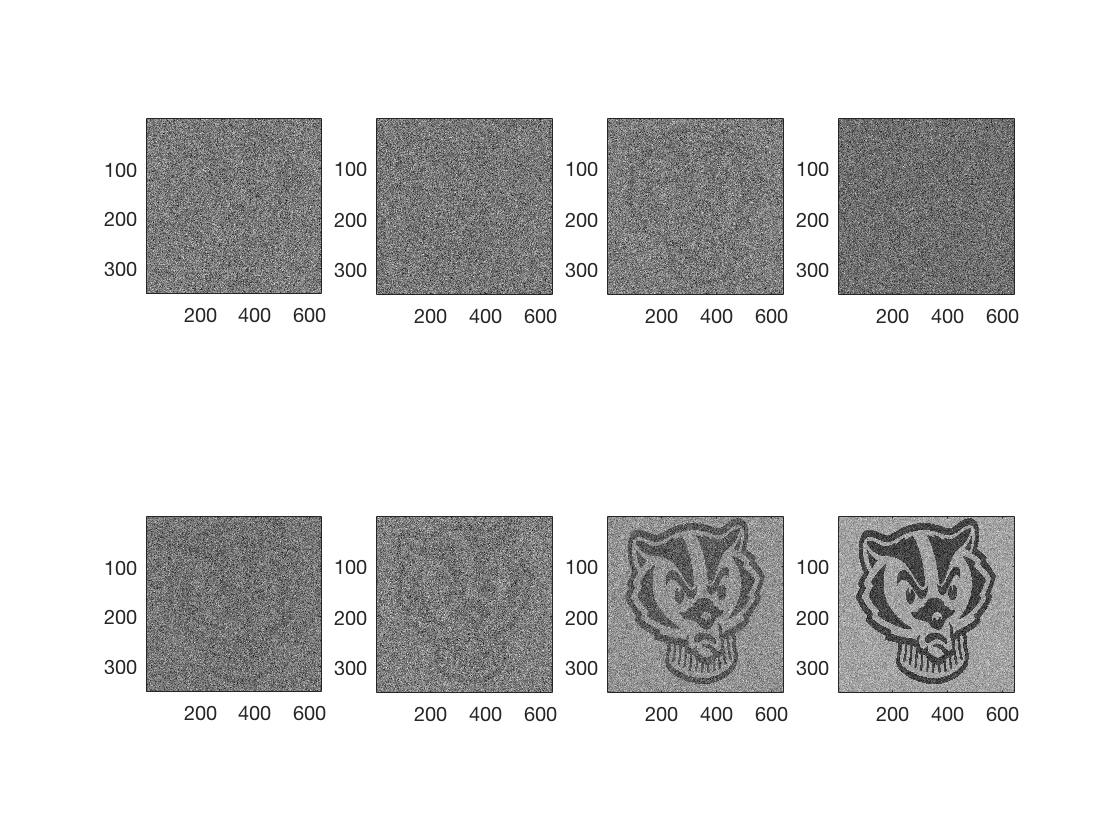

[cnr,idx] = sort(img_cnr);

figure
colormap('gray')
for i=1:2
    for j=1:4
        subplot(2,4,(4*(i-1))+j)
        test_img = bucky_images(:,:,idx(4*(i-1)+j));
        minint=min(min(test_img)); 
        test_img=test_img-minint; 
        maxint=max(max(test_img)); 
        test_img=test_img/maxint*63; 
        image(test_img)
        axis('square')
    end
end

Q3.

a. 

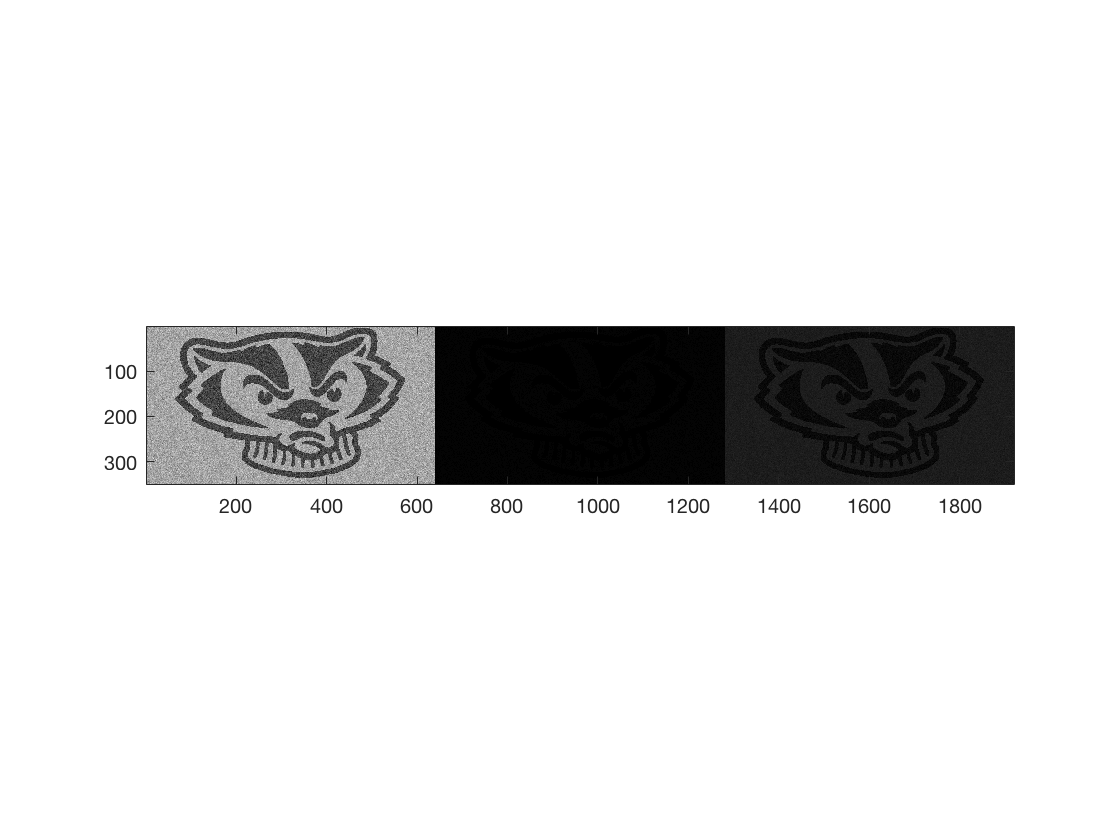

figure
colormap('gray')
minint=min(min(bucky_trio)); 
bucky_trio_new=bucky_trio-minint; 
maxint=max(max(bucky_trio_new)); 
bucky_trio_new=bucky_trio_new/maxint*63; 
image(bucky_trio_new)
axis('image')

b.

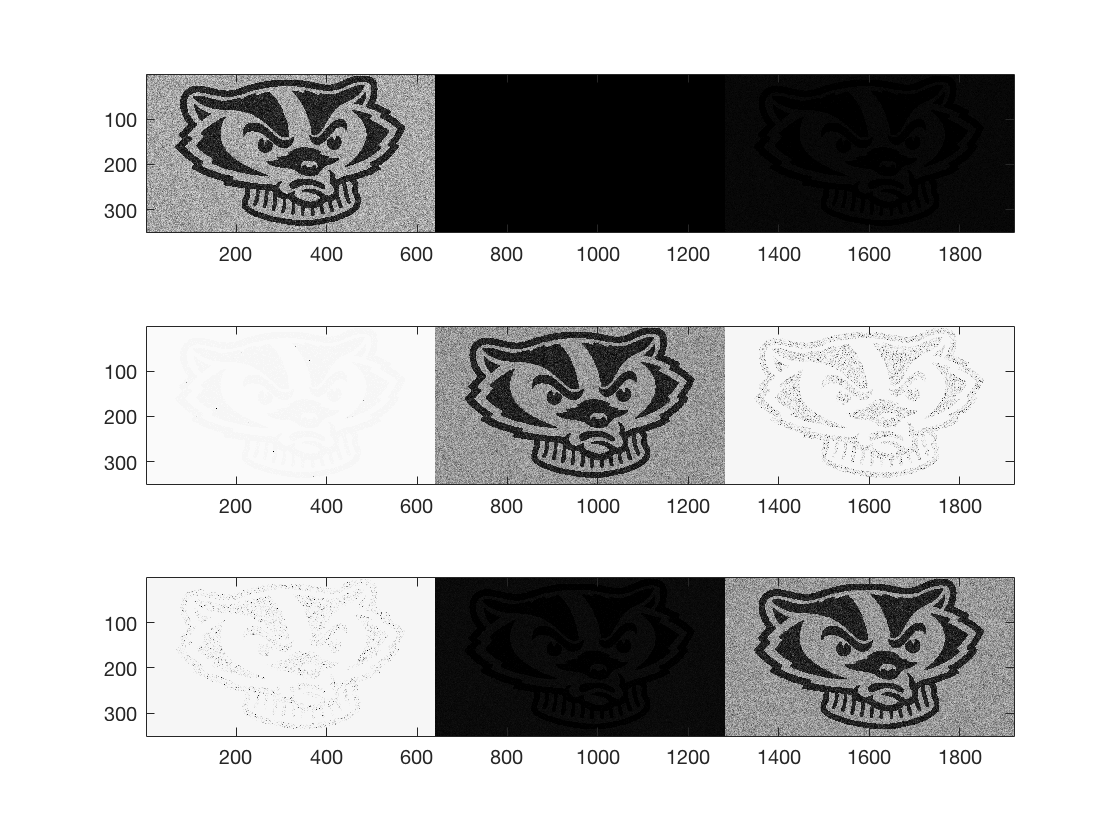

semi_img_1 = bucky_trio(:,1:640);
mean_bucky_1 = mean(semi_img_1(:));
std_bucky_1 = std(semi_img_1(:));
new_img_1=63./(1+exp(-(bucky_trio-mean_bucky_1)/std_bucky_1));
figure
colormap('gray')
subplot(3,1,1)
minint_1=min(min(new_img_1)); 
new_img_1=new_img_1-minint_1; 
maxint_1=max(max(new_img_1)); 
new_img_1=new_img_1/maxint_1*63; 
image(new_img_1)
axis('image')

semi_img_2 = bucky_trio(:,641:1280);
mean_bucky_2 = mean(semi_img_2(:));
std_bucky_2 = std(semi_img_2(:));
new_img_2=63./(1+exp(-(bucky_trio-mean_bucky_2)/std_bucky_2));
subplot(3,1,2)
minint_2=min(min(new_img_2)); 
new_img_2=new_img_2-minint_2; 
maxint_2=max(max(new_img_2)); 
new_img_2=new_img_2/maxint_2*63; 
image(new_img_2)
axis('image')

semi_img_3 = bucky_trio(:,1281:1920);
mean_bucky_3 = mean(mean(bucky_trio(:,1281:1920)));
std_bucky_3 = std(semi_img_3(:));
new_img_3=63./(1+exp(-(bucky_trio-mean_bucky_3)/std_bucky_3));
subplot(3,1,3)
minint_3=min(min(new_img_3)); 
new_img_3=new_img_3-minint_3; 
maxint_3=max(max(new_img_3)); 
new_img_3=new_img_3/maxint_3*63; 
image(new_img_3)
axis('image')

c. The overall intensity of pixels in each portions differs. The first portion has less than moderate black intensity, the second portion has extreme black intensity and the third portion has more than moderate black intensity. To make the images of bucky visible. We will have to reduce/increase the overall intensities of the images. So for first image when we increase the intensity, the other two portions completely become invisible(extremely black) because of overall intensity increase. For second, when we reduce the overall intensity drastically, the first portion becomes invisible(extremely white). And for third when we reduce the intensity a little bit, the first portion becomes hardly visible due to reduced black intensity.

Q4.

a. The windowing parameters required for the question will be lower = 125 and upper = 245, because most of the information is contained within this range

lower = 125

lower = 125

upper = 245

upper = 245

b. The weights used for gray scaling are 0.005 for red, 1.55 for green, 0.005 for blue because most of the  information regarding retinopathy is contained in green channel.

c.

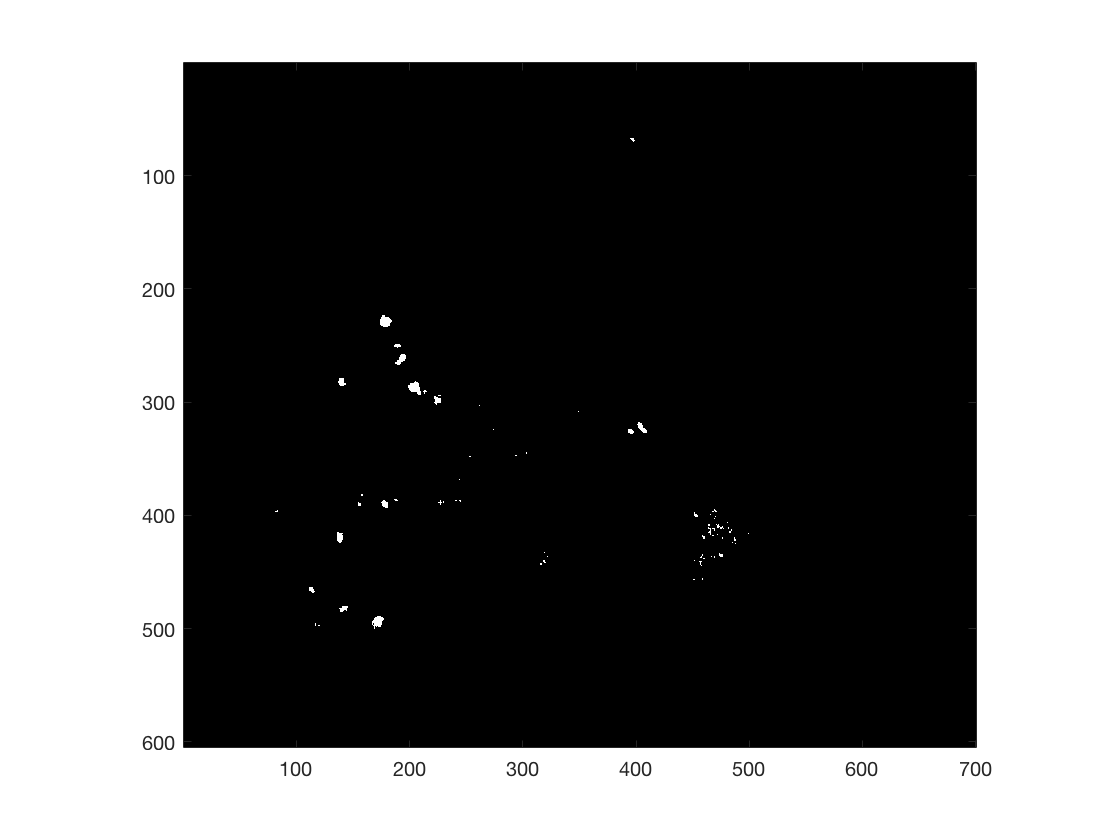

gray = 0.005*img_029(:,:,1)+1.55*img_029(:,:,2)+0.005*img_029(:,:,3);
gray(gray<lower) = 0;
gray(gray>upper) = 255;
gray(gray>=lower & gray<=upper) = (255/(upper-lower))*gray(gray>=lower & gray<=upper) -255*lower/(upper-lower);

figure
colormap('gray')
minint=min(min(gray(:))); 
gray=gray-minint; 
maxint=max(max(gray(:))); 
gray=gray/maxint*63; 
image(gray)
axis('image')

Q5.

fp=fopen('/Users/sparshagarwal/OneDrive/Spring 2018/CS 567/Medical-Imaging/HW 2/SKULLBASE.DCM', 'r'); 
fseek(fp,1622,'bof'); 
img=zeros(512,512); 
img(:)=fread(fp,(512*512),'short'); 
fclose(fp);

a.

diffimg=zeros(512,512);
for i=1:511 
    for j=1:511 
        diffimg(i,j) = -img(i,j) + img(i+1,j); 
    end 
end 

minint=min(min(diffimg)); 
diffimg=diffimg-minint; 
maxint=max(max(diffimg)); 
diffimg=diffimg/maxint*63; 

convmat_x = zeros(3,3);
convmat_x(2,2) = -1;
convmat_x(1,2) = 1

convmat_x =      0     1     0
     0    -1     0
     0     0     0


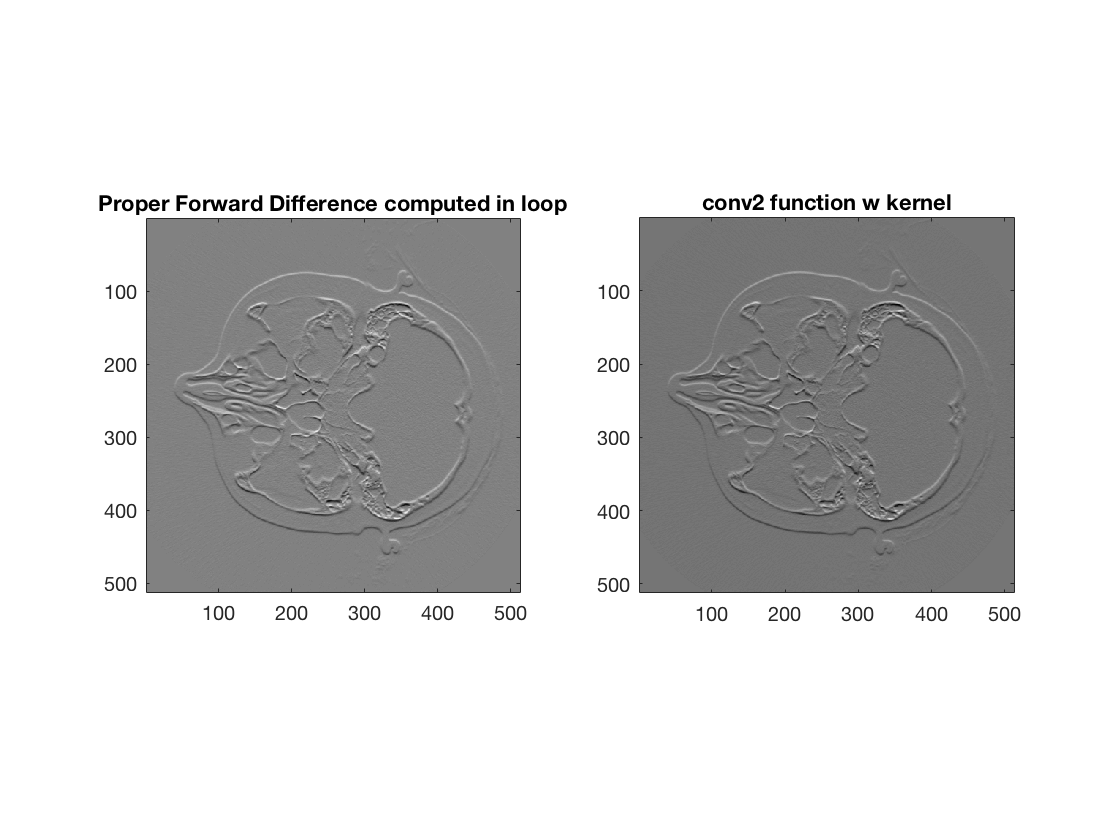

conv_out_x = conv2(img, convmat_x, 'same');

figure
subplot(1,2,1)
image(diffimg) 
axis('image')
title('Proper Forward Difference computed in loop')
subplot(1,2,2)
minint=min(min(conv_out_x)); 
conv_out_x=conv_out_x-minint; 
maxint=max(max(conv_out_x)); 
conv_out_x=conv_out_x/maxint*63; 
image(conv_out_x)
axis('image')
title('conv2 function w kernel')
colormap('gray')

b.

diffimg=zeros(512,512);
for i=1:511 
    for j=1:511 
        diffimg(i,j) = -img(i,j) + img(i,j+1); 
    end 
end 

minint=min(min(diffimg)); 
diffimg=diffimg-minint; 
maxint=max(max(diffimg)); 
diffimg=diffimg/maxint*63; 

convmat_y = zeros(3,3);
convmat_y(2,2) = -1;
convmat_y(2,1) = 1

convmat_y =      0     0     0
     1    -1     0
     0     0     0


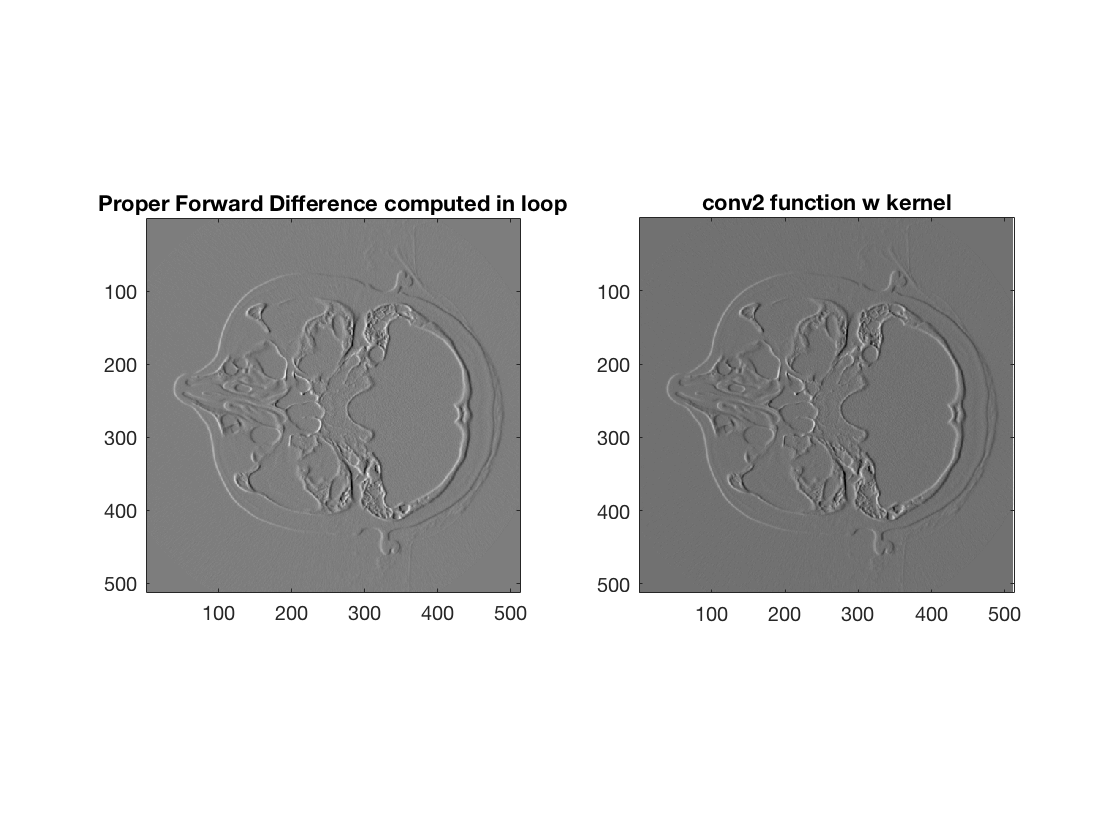


conv_out_y = conv2(img, convmat_y, 'same');

figure
subplot(1,2,1)
image(diffimg) 
axis('image')
title('Proper Forward Difference computed in loop')
subplot(1,2,2)
minint=min(min(conv_out_y)); 
conv_out_y=conv_out_y-minint; 
maxint=max(max(conv_out_y)); 
conv_out_y=conv_out_y/maxint*63; 
image(conv_out_y)
axis('image')
title('conv2 function w kernel')
colormap('gray')

c.

convmat_x = zeros(3,3);
convmat_x(3,2) = -0.5;
convmat_x(1,2) = 0.5

convmat_x =          0    0.5000         0
         0         0         0
         0   -0.5000         0



conv_out_x = conv2(img, convmat_x, 'same');

convmat_y = zeros(3,3);
convmat_y(2,3) = -0.5;
convmat_y(2,1) = 0.5

convmat_y =          0         0         0
    0.5000         0   -0.5000
         0         0         0


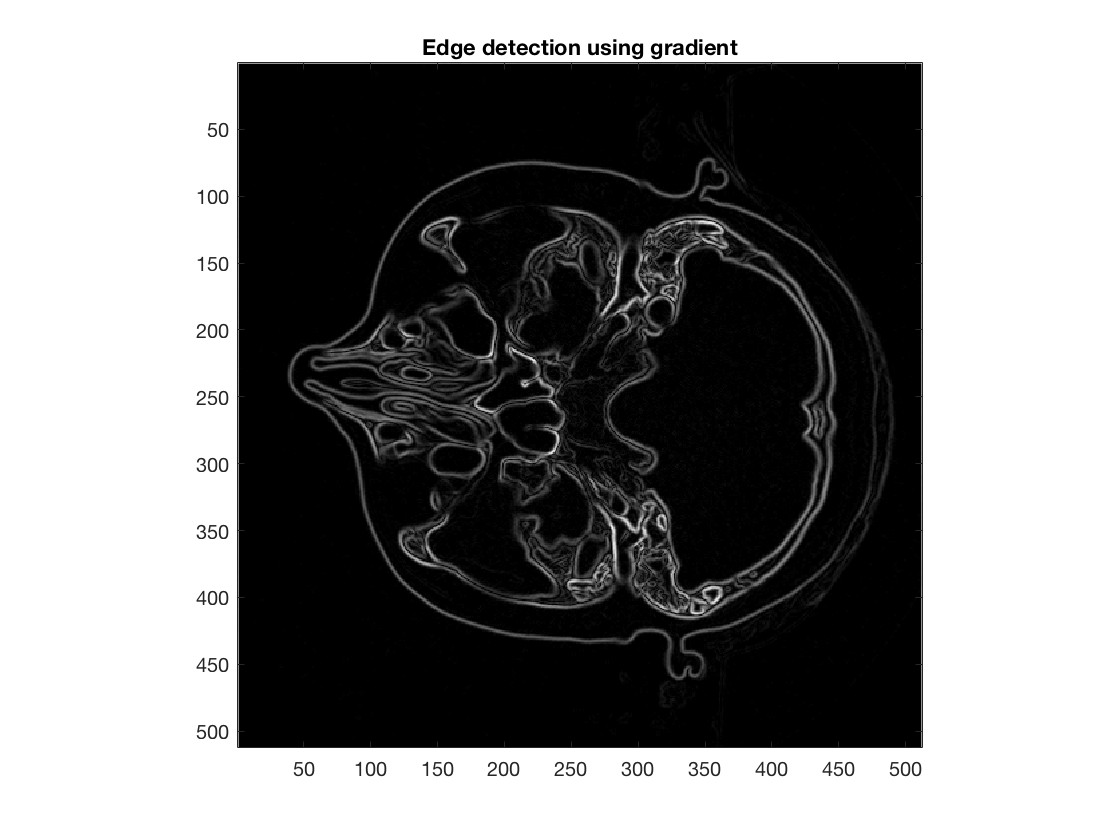


conv_out_y = conv2(img, convmat_y, 'same');

grad = sqrt(conv_out_x.^2+conv_out_y.^2);

figure
minint=min(min(grad)); 
grad=grad-minint; 
maxint=max(max(grad)); 
grad=grad/maxint*63; 
image(grad) 
axis('image')
title('Edge detection using gradient')
colormap('gray')